# Naive Bayes for Titanic data classification 

## Load the Titanic data and show it

Train= readtable('titanic\train.csv');
Test = readtable('titanic\test.csv');
head(Train)

ans = 8×12 table
    PassengerId    Survived    Pclass                             Name                                 Sex        Age    SibSp    Parch      Ticket       Fare       Cabin       Embarked
    ___________    ________    ______    _______________________________________________________    __________    ___    _____    _____    __________    ______    __________    ________

         1            0          3       {'Braund, Mr. Owen Harris'                            }    {'male'  }     22      1        0             NaN      7.25    {0×0 char}     {'S'}  
         2            1          1       {'Cumings, Mrs. John Bradley (Florence Briggs Thayer)'}    {'female'}     38      1        0             NaN    71.283    {'C85'   }     {'C'}  
         3            1          3       {'Heikkinen, Miss. Laina'                             }    {'female'}     26      0        0             NaN     7.925    {0×0 char}     {'S'}  
         4            1          1       {'Futrelle,

head(Test)

ans = 8×11 table
    PassengerId    Pclass                          Name                             Sex        Age     SibSp    Parch      Ticket       Fare       Cabin       Embarked
    ___________    ______    ________________________________________________    __________    ____    _____    _____    __________    ______    __________    ________

        892          3       {'Kelly, Mr. James'                            }    {'male'  }    34.5      0        0      3.3091e+05    7.8292    {0×0 char}     {'Q'}  
        893          3       {'Wilkes, Mrs. James (Ellen Needs)'            }    {'female'}      47      1        0      3.6327e+05         7    {0×0 char}     {'S'}  
        894          2       {'Myles, Mr. Thomas Francis'                   }    {'male'  }      62      0        0      2.4028e+05    9.6875    {0×0 char}     {'Q'}  
        895          3       {'Wirz, Mr. Albert'                            }    {'male'  }      27      0        0      3.1515e+05    8.6625 

## Make the prediction by "sex"

disp(grpstats(Train(:,{'Survived','Sex'}), 'Sex'))

                 Sex        GroupCount    mean_Survived
              __________    __________    _____________

    male      {'male'  }       577           0.18891   
    female    {'female'}       314           0.74204   



gendermdl = grpstats(Train(:,{'Survived','Sex'}), {'Survived','Sex'});
all_female = (gendermdl.GroupCount('0_male') + gendermdl.GroupCount('1_female'))/(577+314);
disp(all_female)

    0.7868



## Preprocess the NaN values

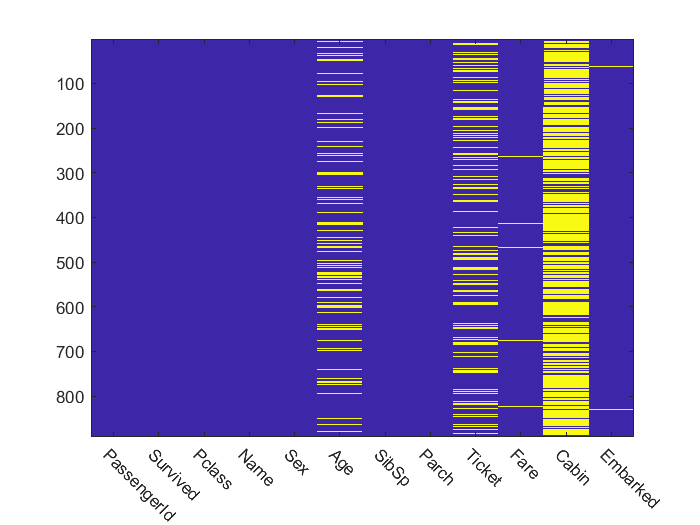

Train.Fare(Train.Fare == 0) = NaN;      % treat 0 fare as NaN
Test.Fare(Test.Fare == 0) = NaN;        % treat 0 fare as NaN
vars = Train.Properties.VariableNames;  % extract column names
figure
imagesc(ismissing(Train))
set(gca,'XTick', 1:12,'XTickLabel',vars);
xtickangle(-45)

% 用平均年龄代替 NaN 年龄
avgAge = nanmean(Train.Age)             % get average age

avgAge = 29.6991

Train.Age(isnan(Train.Age)) = avgAge;   % replace NaN with the average
Test.Age(isnan(Test.Age)) = avgAge; 

% 用同一等级舱的平均票价代替 NaN 船票
fare = grpstats(Train(:,{'Pclass','Fare'}),'Pclass');   % get class average
disp(fare)

         Pclass    GroupCount    mean_Fare
         ______    __________    _________

    1      1          216         86.149  
    2      2          184         21.359  
    3      3          491         13.788  




for i = 1:height(fare) % for each |Pclass|
    % 用 Pclass average 替代缺失的船票值
    Train.Fare(Train.Pclass == i & isnan(Train.Fare)) = fare.mean_Fare(i);
    Test.Fare(Test.Pclass == i & isnan(Test.Fare)) = fare.mean_Fare(i);
end

% Multi Cabins，No Cabin etc.
train_cabins = cellfun(@strsplit, Train.Cabin, 'UniformOutput', false); %strsplit在指定分隔符处拆分字符串或字符向量。以元胞数组形式返回输出值，请指定'UniformOutput',false。
test_cabins = cellfun(@strsplit, Test.Cabin, 'UniformOutput', false);

% count the number of tokens
Train.nCabins = cellfun(@length, train_cabins); %返回船舱位置字符串长度
Test.nCabins = cellfun(@length, test_cabins);

% 处理特殊情况 - 只有一等舱的乘客有多个船舱
Train.nCabins(Train.Pclass ~= 1 & Train.nCabins > 1,:) = 1;
Test.nCabins(Test.Pclass ~= 1 & Test.nCabins > 1,:) = 1;

% if |Cabin| is empty, then |nCabins| should be 0
Train.nCabins(cellfun(@isempty, Train.Cabin)) = 0; %isempty判断是否为空
Test.nCabins(cellfun(@isempty, Test.Cabin)) = 0;

% Embarked is not available
% get most frequent value
disp(grpstats(Train(:,{'Survived','Embarked'}), 'Embarked'))

         Embarked    GroupCount    mean_Survived
         ________    __________    _____________

    S     {'S'}         644           0.33696   
    C     {'C'}         168           0.55357   
    Q     {'Q'}          77           0.38961   



% apply it to missling value
for i = 1 : 891
    if isempty(Train.Embarked{i})
        Train.Embarked{i}='S';
    end
end

for i = 1 : 418
    if isempty(Test.Embarked{i})
        Test.Embarked{i}='S';
    end
end

% 将数据类型从分类型转换为double型
Train.Embarked = double(cell2mat(Train.Embarked)); %cell2mat将元胞数组转化为普通数组
Test.Embarked = double(cell2mat(Test.Embarked));

% change Sex to tpye "double"
for i = 1 : 891
    if strcmp(Train.Sex{i} ,'male') %比较函数strmp()
        Train.Sex{i}=1;
    else
        Train.Sex{i}=0;
    end
end

for i = 1 : 418
    if strcmp(Test.Sex{i} ,'male')
        Test.Sex{i}=1;
    else
        Test.Sex{i}=0;
    end
end
Train.Sex = cell2mat(Train.Sex);
Test.Sex = cell2mat(Test.Sex);

% Del some columns
Train(:,{'Name','Ticket','Cabin','SibSp','Parch'}) = [];
Test(:,{'Name','Ticket','Cabin','SibSp','Parch'}) = [];


## Visulization

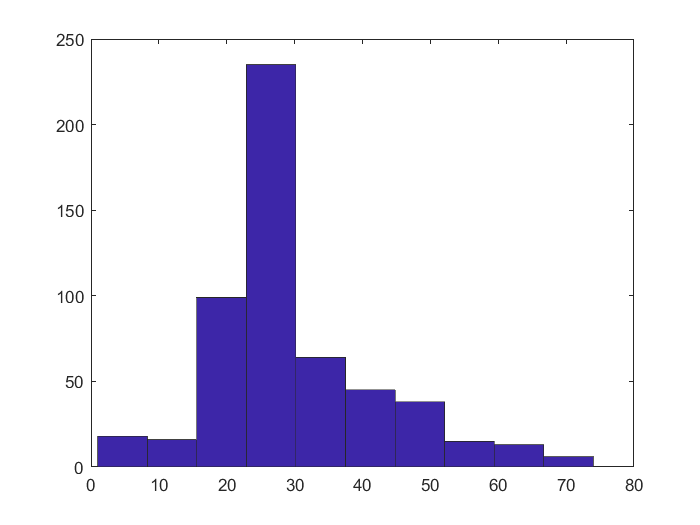

% Age - survived
figure
hist (Train.Age(Train.Survived == 0))   % 死者的年龄柱状图

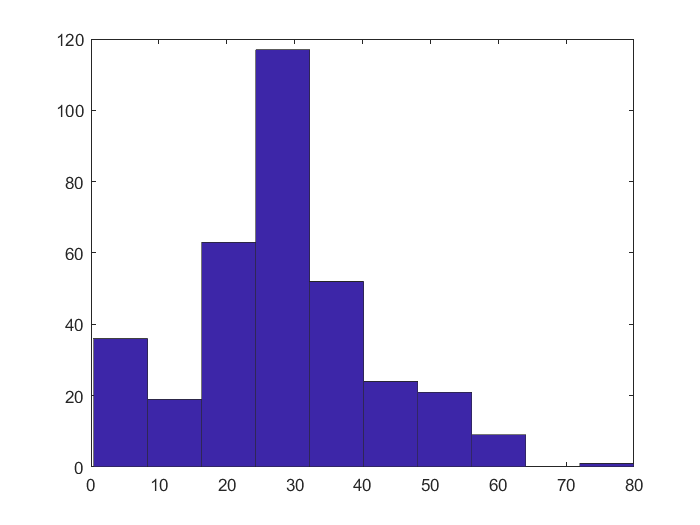

figure
hist (Train.Age(Train.Survived == 1))   % 幸存者的年龄柱状图

data = Train.Variables;
t = data(:,3:8);
l = data(:,2);
X = t';
X = zscore(X,0,2);
y = (l+1)';
idx = randperm(891);
X_train = X(:,idx(1:700));
y_train = y(idx(1:700));
X_test = X(:,idx(701:891));
y_test = y(idx(701:891));
[pw,my_m,my_std] = titanic_NB(X_train,y_train);
[post_p,test_lab] = titanic_testNB(X_test,pw,my_m,my_std,2,6);
right = y_test == test_lab;
rate = sum(right)/length(y_test);
disp(['NB Accuracy:' num2str(rate*100) '%']);

NB Accuracy:78.534%



%测试Test
data1 = Test.Variables;
t1 = data1(:,2:7);
X1 = (t1)';
X1 = zscore(X1,0,2);
[post_p,Test_labs] = titanic_testNB(X1,pw,my_m,my_std,2,6);
PassengerId=[1:1:418]';
Survived=Test_labs(1,:)';
Survived=Survived-1;
T=table(PassengerId,Survived)

T = 418×2 table
    PassengerId    Survived
    ___________    ________

         1            0    
         2            0    
         3            0    
         4            0    
         5            0    
         6            0    
         7            0    
         8            0    
         9            1    
        10            0    
        11            0    
        12            0    
        13            1    
        14            0    
        15            1    
        16            1    


writetable(T,'submission.csv')  
type 'submission.csv'

PassengerId,Survived
1,0
2,0
3,0
4,0
5,0
6,0
7,0
8,0
9,1
10,0
11,0
12,0
13,1
14,0
15,1
16,1
17,0
18,0
19,0
20,1
21,0
22,0
23,1
24,0
25,1
26,0
27,1
28,0
29,0
30,0
31,0
32,0
33,0
34,0
35,1
36,0
37,0
38,0
39,0
40,0
41,0
42,0
43,0
44,1
45,1
46,0
47,1
48,0
49,1
50,0
51,0
52,0
53,1
54,1
55,0
56,0
57,0
58,0
59,0
60,1
61,0
62,0
63,0
64,0
65,1
66,1
67,0
68,0
69,1
70,1
71,0
72,0
73,0
74,1
75,1
76,1
77,0
78,1
79,0
80,0
81,0
82,1
83,0
84,0
85,0
86,0
87,0
88,0
89,0
90,0
91,0
92,0
93,1
94,0
95,0
96,0
97,1
98,0
99,0
100,0
101,1
102,0
103,0
104,0
105,1
106,0
107,0
108,0
109,0
110,0
111,0
112,0
113,1
114,0
115,1
116,0
117,0
118,1
119,1
120,1
121,1
122,0
123,1
124,0
125,0
126,0
127,0
128,0
129,0
130,0
131,0
132,1
133,0
134,0
135,0
136,0
137,0
138,0
139,0
140,0
141,1
142,1
143,1
144,0
145,0
146,0
147,0
148,0
149,0
150,0
151,1
152,0
153,0
154,0
155,0
156,0
157,1
158,0
159,0
160,0
161,0
162,0
163,1
164,0
165,0
166,0
167,1
168,0
169,1
170,0
171,0
172,0
173,0
174,0
175,0
176,1
177,1
178,1
179,1
180,1
181,0
1